**1. Generating Morlet Wavelets**

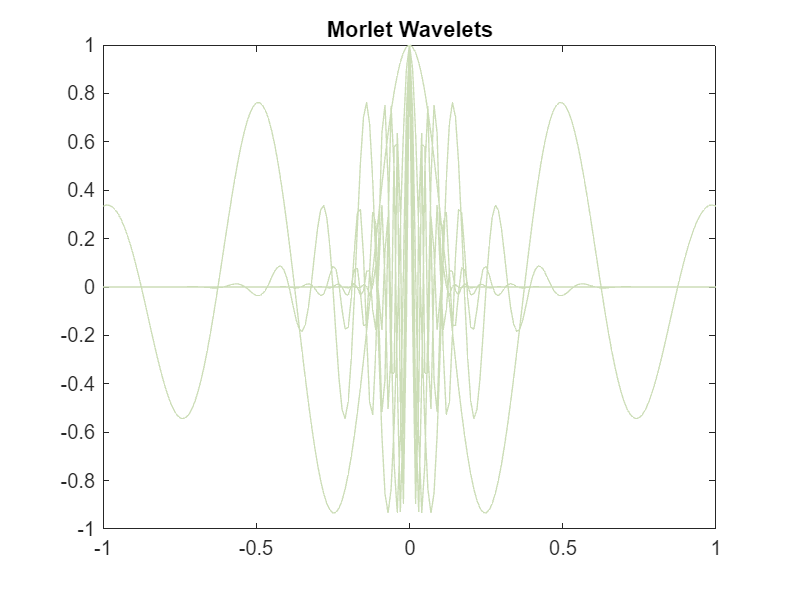

srate = 100;
time = -1:1/srate:1;

s = 6;
g_window = exp(-time.^2./(2*s^2));

m_wlet_space = zeros([length(2:5:30),length(time)]);

figure;
for f = 2:5:30
    s = 6/(2*pi*f);

    g_window = exp(-time.^2./(2*s)^2);
    s_wave = exp(2*pi*1i*f*time);

    m_wlet = s_wave.*g_window;
    m_wlet_space(find(f == 2:5:30),:) = m_wlet;

    plot(time,real(m_wlet), Color="#CCDDB7")
    hold on

end
title("Morlet Wavelets")

load sampleEEGdata.mat

**2. Convolving the family of Morlet Wavelet with all the trials**

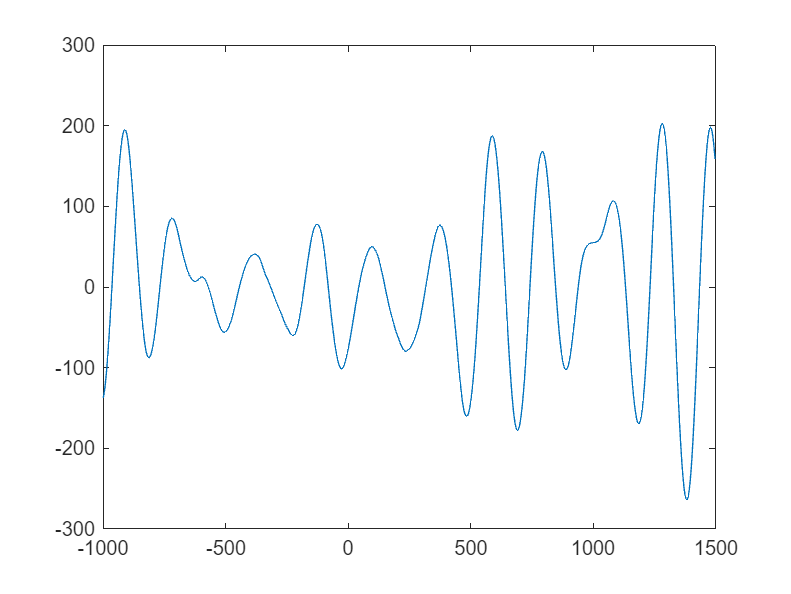

signals = squeeze(EEG.data(1,:,:));
n_conv = length(m_wlet) + EEG.pnts - 1;

hw_size = ceil(length(m_wlet)/2);

fft_s = fft(signals, n_conv)';
fft_w = fft(m_wlet_space', n_conv)';
fft_c = zeros([EEG.trials,n_conv,length(2:5:30)]);

for i = 1:length(5:5:30)
    fft_c(:,:,i) = fft_s.*fft_w(i,:);
end

conv_result = ifft(fft_c,n_conv,2);

figure;
plot(EEG.times, imag(conv_result(1,hw_size:end-hw_size + 1,1)))

**3. Finding the ERP of the wavelet convolved data**

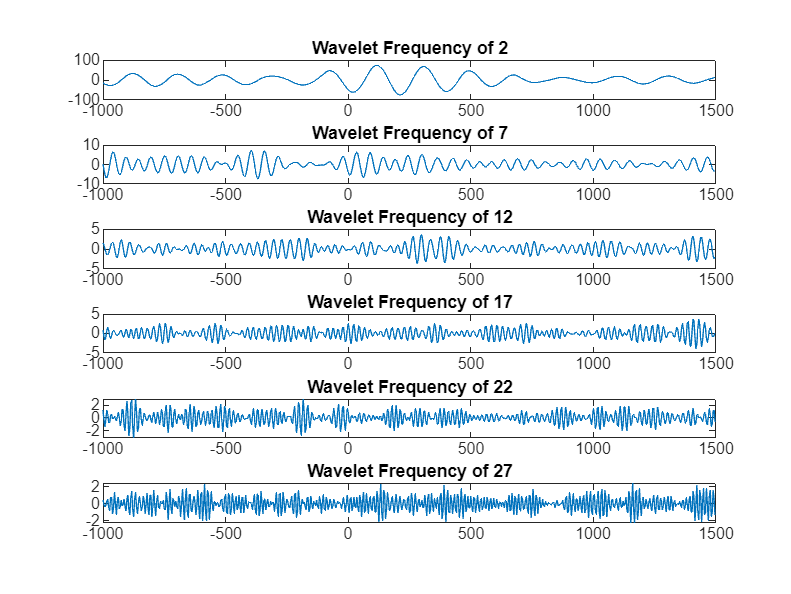

erp_data = squeeze(mean(conv_result,1));

freq = 2:5:30;

figure;
for i = 1:6
    subplot(6,1,i)
    plot(EEG.times, erp_data(hw_size:end - hw_size + 1,i))
    title("Wavelet Frequency of "+freq(i))
end

**4. Relating Wavelet Convolved ERP with Broadband ERP**

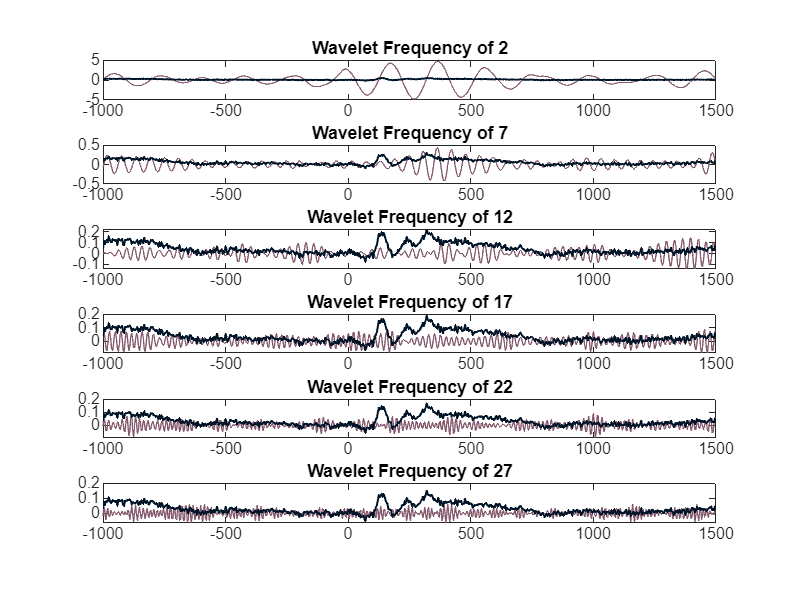

erp_data_b = mean(signals,2)';

figure;
for i = 1:6
    s = 6/(2*pi*freq(i));
    subplot(6,1,i)
    plot(EEG.times, erp_data(hw_size:end - hw_size + 1,i)*sqrt(s)/10, Color="#845A6D")
    hold on
    plot(EEG.times, erp_data_b*sqrt(s)/10, Color="#001427", LineWidth=1)
    hold off
    title("Wavelet Frequency of "+freq(i))
end